## 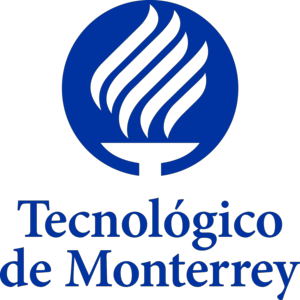

**Instituto Tecnológico y de Estudios Superiores de Monterrey**

# Simulación de las leyes de conservación

Luis Alfonso Pérez Mijangos A01653848

Elí Salomón Martínez Hernández A01653876

Héctor Miranda García A01658845

Francisco Samuel Mercado Sandoval A01660585

Diciembre, 2020

clc;
clear;

 

vi = 50; % km/h
vi = vi / 3.6; % m/s
thpt1 = 25; % grados
thpt2 = 0; % grados
mu = 0.867;

xi = 30;    yi = 230;   % (30, 230)
xf = 260;   yf = 80;    % (260, 80)
x1 = 80;    y1 = 200;   % (80, 200)
x2 = 180;   y2 = 220;   % (180, 220)

ry = [yi; y1; y2; yf];
rx = [xi^3 xi^2 xi 1;
      x1^3 x1^2 x1 1;
      x2^3 x2^2 x2 1;
      xf^3 xf^2 xf 1];

cofs = rx\ ry;

a = cofs(1)

a = -7.0290e-05

b = cofs(2)

b = 0.0257

c = cofs(3)

c = -2.7471

d = cofs(4)

d = 291.1652


syms k

f    = @(x) (a*(x.^3) + (b*(x.^2)) + (c*x) + d);    % definición de la función cúbica
fdt  = @(x) (a*(3*x.^2) + (b*(2*x)) + c);           % derivada de la función
f2dt = @(x) (6*a*x + b*2);                          % segunda derivada de la función

x = xi:xf;
y = f(x);
z = f(x)*0;

% Longitud de la pista
lfdt = @(x) sqrt(1 + fdt(x).^2);
longitudPista = integral(lfdt, xi, xf);
fprintf("La longitud de la pista es de %4.3f m", longitudPista)

La longitud de la pista es de 330.985 m


% Puntos críticos
fkdt  = (a*(3*k.^2) + (b*(2*k)) + c);                % derivada de la función
crit = vpasolve(fkdt == 0, k);
fprintf("Máx: (%4.3f, %4.3f)", crit(1), f(crit(1)))

Máx: (78.988, 199.991)

fprintf("Min: (%4.3f, %4.3f)", crit(2), f(crit(2)))

Min: (164.929, 222.299)


% Punto de inflexión
fk2dt = (6*a*k + b*2);                               % segunda derivada de la función
inf = vpasolve(fk2dt == 0, k);
fprintf("Punto de inflexión: (%4.3f, %4.3f)", inf, f(inf))

Punto de inflexión: (121.959, 211.145)


% Radio de curvatura
r1 = abs(((1 + fdt(crit(1))^2)^(3/2))/f2dt(crit(1)));
r2 = abs(((1 + fdt(crit(2))^2)^(3/2))/f2dt(crit(2)));
fprintf("El radio de la %s curvatura es de %2.3f m\n", ['primera' r1], ['segunda' r2])

El radio de la primera curvatura es de 55.181 m
El radio de la segunda curvatura es de 55.181 m



% Velocidad máxima 
g = 9.81; % m/s
vCrit1 = velocidadCritica(thpt1, g, mu, r1);
vCrit2 = velocidadCritica(thpt2, g, mu, r2);
fprintf("La velocidad máxima a la que el coche puede ir en la %s curva es de %4.3f km/h \n", ['primer' (3.6 * vCrit1)], ['segunda' (3.6 * vCrit2)])

La velocidad máxima a la que el coche puede ir en la primer curva es de 125.308 km/h 
La velocidad máxima a la que el coche puede ir en la segunda curva es de 77.990 km/h 



% Distancia de derrape
derr = (vi^2)/(2*mu*g);

%% Graficación
close all;
hold on;
grid on;
figure(1)

% Configuración de los ejes
xlabel('x'); ylabel('y'); zlabel('z');
axis([0 350 0 350 0 150]);
view([-26 65]);
camlight;

% Base del mapa
vertices = [0, 0, 0;
            350,0,0;
            350,350,0;
            0,350,0]; 
faces = [1, 2, 3, 4];
patch('Faces', faces, 'Vertices', vertices, 'FaceColor', 'g');

% Diseño ppal. de la pista basado en la función
line(x, y, z+1,'Color','k','LineWidth',7)
line(x, y, z+1,'Color','y','LineStyle','--')

% Puntos críticos y de inflexión
s1 = scatter3(crit(1), f(crit(1)), 5, 'MarkerEdgeColor', 'w', 'MarkerFaceColor', [0 .75 .75]);
s2 = scatter3(crit(2), f(crit(2)), 5, 'MarkerEdgeColor', 'w', 'MarkerFaceColor', [0 .75 .75]);
s3 = scatter3(inf, f(inf), 5, 'MarkerEdgeColor', 'w', 'MarkerFaceColor', [0.8500 0.3250 0.0980]);
s1tx = text(crit(1), f(crit(1)), 5, '\leftarrow Min', 'Color', 'white', 'FontSize', 10);
s2tx = text(crit(2), f(crit(2)), 5, '\leftarrow Máx', 'Color', 'white', 'FontSize', 10);
s3tx = text(inf, f(inf), 5, '\leftarrow Inflexión', 'Color', 'white', 'FontSize', 10);

% Círculos de las curvaturas
circle1 = plotcircle(crit(1), f(crit(1)), fdt(crit(1)), f2dt(crit(1)), r1);
circle2 = plotcircle(crit(2), f(crit(2)), fdt(crit(2)), f2dt(crit(2)), r2);
%r1tx = text(crit(1), f(crit(1)) + r1, 5, ['\leftarrow r1: ', "55.181 m"], 'Color', 'white', 'FontSize', 10);
%r2tx = text(crit(2), f(crit(2)) - r2, 5, ['\leftarrow r2: ', "55.181 m"], 'Color', 'white', 'FontSize', 10);

% Coche
coche = generadorAuto(x(1), y(1), atand(lfdt(1)));
ubicacion = text(x(1),  y(1), 7,['\leftarrow x: ', num2str(y(1))], 'Color','k', 'FontSize', 8);

% Gradas
%generadorGradas(x_location, y_location, z_location, theta_grada)
generadorGradas(35, 195, 0, 130);
generadorGradas(145, 245, 0, 20);

% Distancia gradas-pista
gradas_pista_uno = sqrt(((214-195)^2) + ((44-35)^2));
fprintf("Distancia GradaI-Pista uno: %4.3f", gradas_pista_uno)

Distancia GradaI-Pista uno: 21.024

gradas_pista_dos = sqrt(((245-225)^2) + ((145-135)^2));
fprintf("Distancia GradaI-Pista dos: %4.3f", gradas_pista_dos)

Distancia GradaI-Pista dos: 22.361

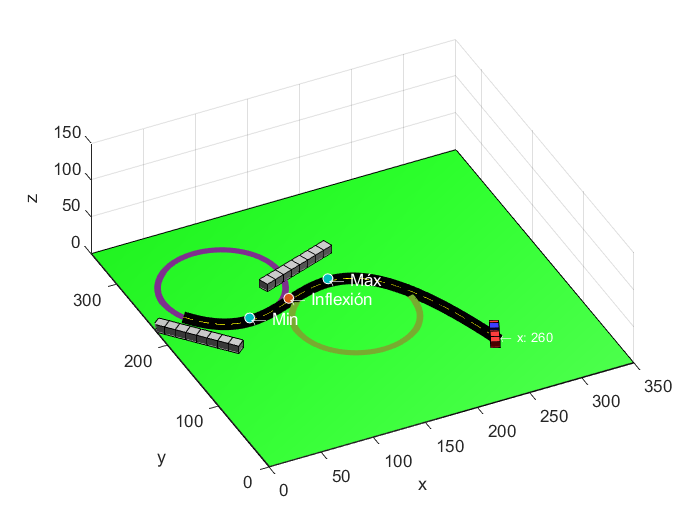


longitudTan = derr;

lim1 = [30 108];
lim2 = [140 200];

for i = 1:5:length(x)
    delete(coche);
    delete(ubicacion);
    
    m = fdt(x(i));
    vx = x(i):x(i) + longitudTan;
    b = y(i) - m*x(i);
    vy = m * vx +b;
    
    if x(i) >= lim1(1) && x(i) <= lim1(2)
        if vi > vCrit1
            plot3(vx, vy, vx*0 + 1, 'LineWidth', 1, 'Color', 'r');    
            for j = 1:5:length(vx)
                delete(coche);
                delete(ubicacion);
                coche = generadorAuto(vx(j), vy(j), atand(lfdt(j)));
                ubicacion = text(vx(j),  vy(j), 7,['\leftarrow x: ', num2str(vx(j))], 'Color','k', 'FontSize', 8);
                pause(0.001)
            end
        else
            ubicacion = text(x(i),  y(i), 7,['\leftarrow x: ', num2str(x(i))], 'Color','w', 'FontSize', 8);
            coche = generadorAuto(x(i), y(i), atand(lfdt(i)));
        end
    elseif x(i) >= lim2(1) && x(i) <= lim2(2)
        if vi > vCrit2
            plot3(vx, vy, vx*0 + 1, 'LineWidth', 1, 'Color', 'r');    
            for j = 1:5:length(vx)
                delete(coche);
                delete(ubicacion);
                coche = generadorAuto(vx(j), vy(j), atand(lfdt(j)));
                ubicacion = text(vx(j),  vy(j), 7,['\leftarrow x: ', num2str(vx(j))], 'Color','k', 'FontSize', 8);
                pause(0.001)
            end
        else
            ubicacion = text(x(i),  y(i), 7,['\leftarrow x: ', num2str(x(i))], 'Color','w', 'FontSize', 8);
            coche = generadorAuto(x(i), y(i), atand(lfdt(i)));
        end 
    else
        ubicacion = text(x(i),  y(i), 7,['\leftarrow x: ', num2str(x(i))], 'Color','w', 'FontSize', 8);
        coche = generadorAuto(x(i), y(i), atand(lfdt(i)));
    end
    pause(0.1)
end

function v_max = velocidadCritica(angle, g, mu, r)
% Función que permite calcular la velocidad máxima a la que puede ir el
% coche en una derterminada curva
    v_max = sqrt(g*r*((sind(angle) + mu*cosd(angle))/(cosd(angle) - mu*sind(angle))));
end

function h = plotcircle(critx,crity, fdtx, f2dtx, r)
% Función que grafica círculos en el mapa
    xs = critx - ((fdtx*(1 + fdtx^2))/f2dtx);   % punto central del círuclo
    ys = crity + ((1 + fdtx^2)/f2dtx);          % punto central del círuclo
    
    th = 0:pi/50:2*pi;
    xunit = r*cos(th) + xs;
    yunit = r*sin(th) + ys;
    h = plot(xunit, yunit, 'LineWidth', 4);
end

function [objeto] = plot_3d_cube(x_length, y_length, z_length, cube_color, x_point, y_point, z_point, theta) %%theta in radian
H=[0 ,1 ,0 ,1 ,0 ,1 ,0 ,1; 0 ,0 ,1 ,1 ,0 ,0 ,1 ,1; 0 ,0 ,0 ,0 ,1 ,1 ,1 , 1];

    sinTheta = sind(theta);
    cosTheta = cosd(theta);
    
    for j = 1 : 1 : 8
        xs = H(1,j);
        ys = H(2,j);
        
        H(1,j) = xs * cosTheta - ys * sinTheta;
        H(2,j) = ys * cosTheta + xs * sinTheta;
    end

byLength = H .* [x_length; y_length; z_length];
H = byLength + [x_point; y_point; z_point];
S=[1 2 4 3; 1 2 6 5; 1 3 7 5; 3 4 8 7; 2 4 8 6; 5 6 8 7];

objeto1 = patch(H(1,S(1,:)),H(2,S(1,:)),H(3,S(1,:)),cube_color);
objeto2 = patch(H(1,S(2,:)),H(2,S(2,:)),H(3,S(2,:)),cube_color);
objeto3 = patch(H(1,S(3,:)),H(2,S(3,:)),H(3,S(3,:)),cube_color);
objeto4 = patch(H(1,S(4,:)),H(2,S(4,:)),H(3,S(4,:)),cube_color);
objeto5 = patch(H(1,S(5,:)),H(2,S(5,:)),H(3,S(5,:)),cube_color);
objeto6 = patch(H(1,S(6,:)),H(2,S(6,:)),H(3,S(6,:)),cube_color);
objeto = [objeto1, objeto2, objeto3, objeto4, objeto5, objeto6];
end

function [gradaFinal]= generadorGradas(x_location, y_location, z_location, theta_grada)
% (x_length, y_length, z_length, cube_color, x_point, y_point, z_point, theta)
    x_l = 10;
    y_l = 10;
    z_l = 10;
    c_color = [0.75 0.75 0.75];
    
  %  if theta_grada >= 0 && theta_grada <= 90
        c1x = x_location + (-35*cosd(theta_grada));
        c1y = y_location + (-35*sind(theta_grada));
        c2x = x_location + (-25* cosd(theta_grada));
        c2y = y_location + (-25*sind(theta_grada));
        c3x = x_location + (-15* cosd(theta_grada));
        c3y = y_location + (-15*sind(theta_grada));
        c4x = x_location + (-5* cosd(theta_grada));
        c4y = y_location + (-5*sind(theta_grada));
        c5x = x_location + (5* cosd(theta_grada));
        c5y = y_location + (5*sind(theta_grada));
        c6x = x_location + (15* cosd(theta_grada));
        c6y = y_location + (15*sind(theta_grada));
        c7x = x_location + (25* cosd(theta_grada));
        c7y = y_location + (25*sind(theta_grada));
        c8x = x_location + (35*cosd(theta_grada));
        c8y = y_location + (35*sind(theta_grada));
        
   % end
    
    C1 = plot_3d_cube(x_l, y_l, z_l, c_color, c1x, c1y, z_location, theta_grada);
    C2 = plot_3d_cube(x_l, y_l, z_l, c_color, c2x, c2y, z_location, theta_grada);
    C3 = plot_3d_cube(x_l, y_l, z_l, c_color, c3x, c3y, z_location, theta_grada);
    C4 = plot_3d_cube(x_l, y_l, z_l, c_color, c4x, c4y, z_location, theta_grada);
    C5 = plot_3d_cube(x_l, y_l, z_l, c_color, c5x, c5y, z_location, theta_grada);
    C6 = plot_3d_cube(x_l, y_l, z_l, c_color, c6x, c6y, z_location, theta_grada);
    C7 = plot_3d_cube(x_l, y_l, z_l, c_color, c7x, c7y, z_location, theta_grada);
    C8 = plot_3d_cube(x_l, y_l, z_l, c_color, c8x, c8y, z_location, theta_grada);
    
    gradaFinal = [C1, C2, C3, C4, C5, C6, C7, C8];
end


% (x_length, y_length, z_length, cube_color, x_point, y_point, z_point, theta)

function [carrito] = generadorAuto(xp, yp, theta)
    
    p1x = xp + (-12*cosd(theta));
    p1y = yp + (-12*sind(theta));
    p2x = xp + (-4*cosd(theta));
    p2y = yp + (-4*sind(theta));
    p3x = xp + (4*cosd(theta));
    p3y = yp + (4*sind(theta));
    p4x = xp + (12*cosd(theta));
    p4y = yp + (12*sind(theta));
    p5x = xp + (4*cosd(theta));
    p5y = yp + (4*sind(theta));
    
    
    car1 = plot_3d_cube(8, 8, 8, 'r', p1x, p1y, 2, theta);
    car2 = plot_3d_cube(8, 8, 8, 'r', p2x, p2y, 2, theta);
    car3 = plot_3d_cube(8, 8, 8, 'r', p3x, p3y, 2, theta);
    car4 = plot_3d_cube(8, 8, 8, 'r', p4x, p4y, 2, theta);
    car5 = plot_3d_cube(8, 8, 8, 'b', p5x, p5y, 6, theta);
    
    carrito = [car1, car2, car3, car4, car5];
end